% Set the parameters
N = 40;
a = 1;
d = -0.01;
x_bar = 1;
gamma = 10.^(-3:0);
A = genA(d, a, N);
b = genb(x_bar, a, N);

% Compute u_RLS
u_RLS_lam = @(gamma_arr) u_RLS(d,a,x_bar,gamma_arr,N);
us = cell2mat(arrayfun(u_RLS_lam, gamma, UniformOutput=false));
us = flip(us, 2); % flip to get in decreasing order of gamma

get_x_vec = @(u_vec) get_x(A, u_vec, b);
xs = [x_bar x_bar x_bar x_bar; get_x_vec(us)];

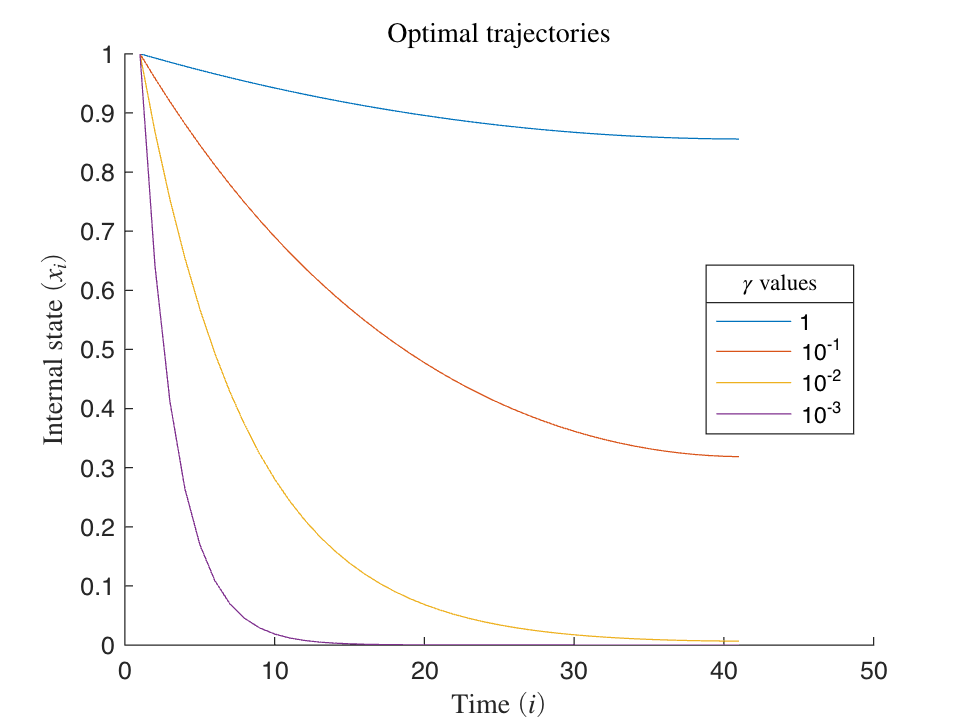

clf
hold on
plot(xs)
title("Optimal trajectories", "Interpreter", "latex");
leg = legend('1', '10^{-1}', '10^{-2}', '10^{-3}', "Location","best");
title(leg, "$\gamma$ values", "Interpreter","latex");
xlabel("Time $(i)$", 'Interpreter','latex')
ylabel("Internal state $\left(x_i\right)$", 'Interpreter','latex');
hold off

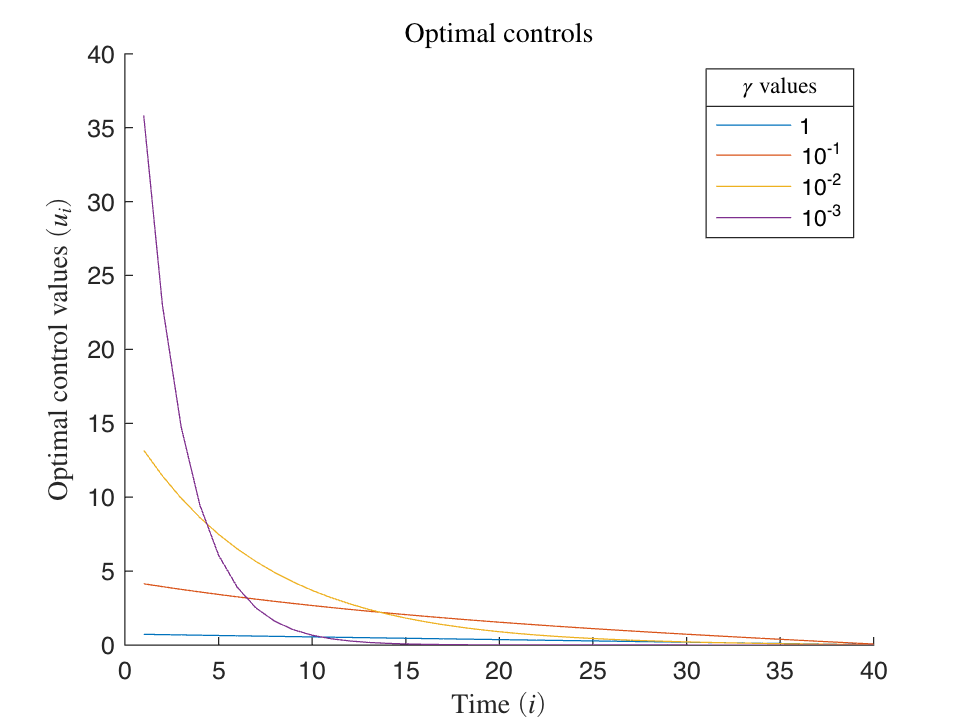

clf
hold on
plot(us)
title("Optimal controls", "Interpreter","latex");
leg = legend('1', '10^{-1}', '10^{-2}', '10^{-3}', "Location","best");
title(leg, "$\gamma$ values", "Interpreter","latex");
xlabel("Time $(i)$", 'Interpreter','latex')
ylabel("Optimal control values $\left(u_i\right)$", 'Interpreter','latex');
hold off